# Running Forward Kinematics in CASPR

This tutorial shows how to run inverse kinematics through two approaches:

- ForwardKinematicsSimulator

- Writing your own time loop

## Setup

The following steps are required for both approaches.

###     1) Load the robot and trajectory

    Load a robot as shown in `tutorial_load_robot.mlx `and` tutorial_load_trajectory.mlx`

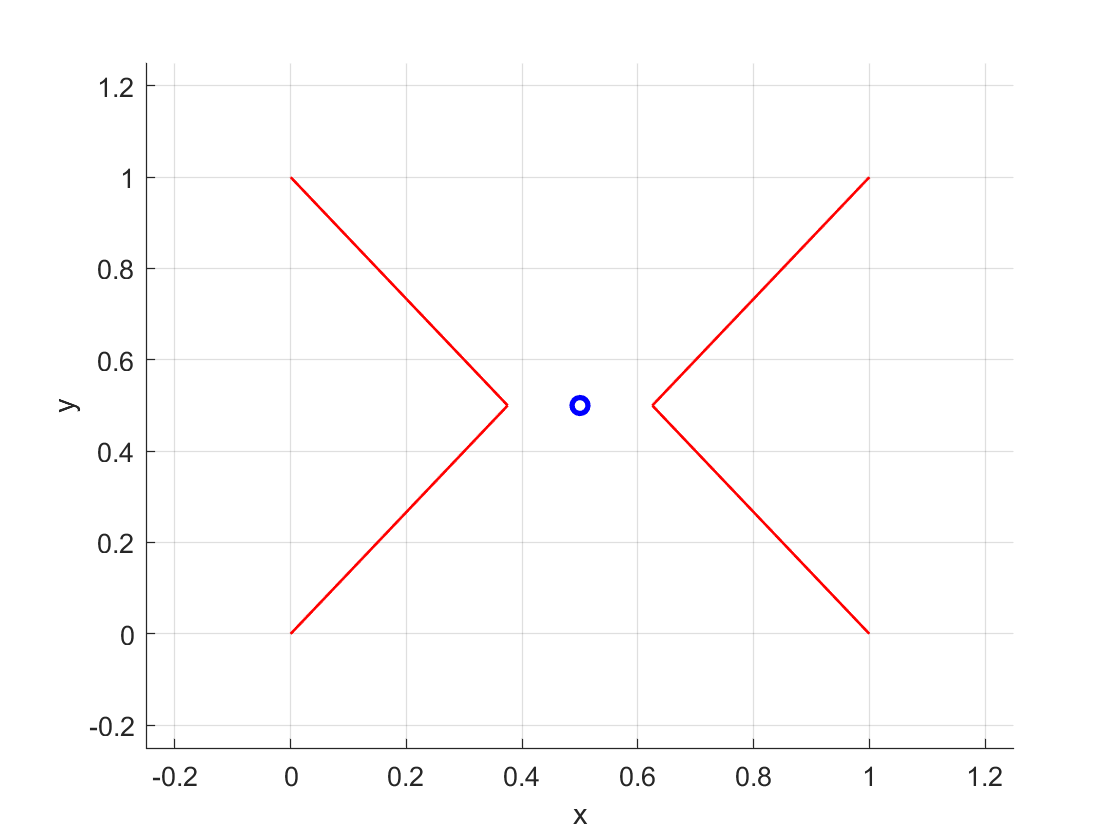

model_config = ModelConfig('Example planar XY');
cdpr_model = model_config.getModel('basic');
trajectory = model_config.getJointTrajectory('example_quintic');
MotionSimulatorBase.PlotFrame(cdpr_model, model_config.displayRange, model_config.viewAngle); % Plot robot

###     2) Run  inverse kinematics 

    This is required just to obtain cable lengths as input to the forward kinematics. The steps are the same as that from `tutorial_IK.mlx`

ik_sim = InverseKinematicsSimulator(cdpr_model);
ik_sim.run(trajectory);

[INFO] Begin inverse kinematics simulator run...
[INFO] Time : 0.000000
[INFO] Time : 0.010000
[INFO] Time : 0.020000
[INFO] Time : 0.030000
[INFO] Time : 0.040000
[INFO] Time : 0.050000
[INFO] Time : 0.060000
[INFO] Time : 0.070000
[INFO] Time : 0.080000
[INFO] Time : 0.090000
[INFO] Time : 0.100000
[INFO] Time : 0.110000
[INFO] Time : 0.120000
[INFO] Time : 0.130000
[INFO] Time : 0.140000
[INFO] Time : 0.150000
[INFO] Time : 0.160000
[INFO] Time : 0.170000
[INFO] Time : 0.180000
[INFO] Time : 0.190000
[INFO] Time : 0.200000
[INFO] Time : 0.210000
[INFO] Time : 0.220000
[INFO] Time : 0.230000
[INFO] Time : 0.240000
[INFO] Time : 0.250000
[INFO] Time : 0.260000
[INFO] Time : 0.270000
[INFO] Time : 0.280000
[INFO] Time : 0.290000
[INFO] Time : 0.300000
[INFO] Time : 0.310000
[INFO] Time : 0.320000
[INFO] Time : 0.330000
[INFO] Time : 0.340000
[INFO] Time : 0.350000
[INFO] Time : 0.360000
[INFO] Time : 0.370000
[INFO] Time : 0.380000
[INFO] Time : 0.390000
[INFO] Time : 0.400000
[INFO] T

Original joint pose (to be solved using FK):

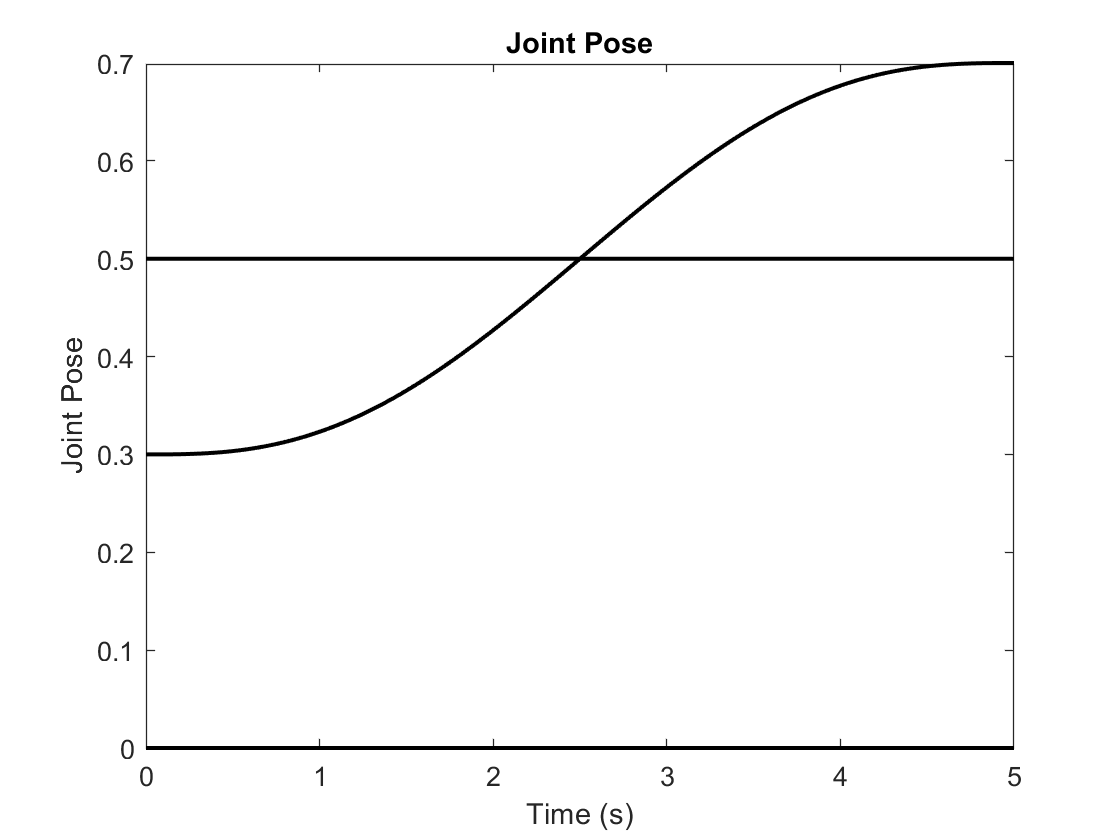

ik_sim.plotJointPose();

###     3) Define the forward kinematics solver(s)

    Since there are many potential ways to solve for the forward kinematics, CASPR offer different solvers that can be used for the simulator. For example, using the simplest differential method:

fk_diff_solver = FKDifferential(cdpr_model); % Refer to FKDifferential.m for more details

    Or you could also define another type, the most common non-linear least squares method:

fk_least_squares_solver = FKLeastSquares(cdpr_model, FK_LS_ApproxOptionType.FIRST_ORDER_INTEGRATE_PSEUDOINV, FK_LS_QdotOptionType.FIRST_ORDER_DERIV); % Refer to FKLeastSquares.m for more details

    Setup some initial values for use later:

init_q = ik_sim.trajectory.q{1}; % Initial q for the solver
init_q_dot = ik_sim.trajectory.q_dot{1}; % Initial q_dot for the solver

## Using the ForwardKinematicsSimulator

The Forward`KinematicsSimulator` provides the simplest way to run a "standard" forward kinematics simulation for a defined trajectory. 

###     1) Create the simulator

    First, create the simulator object using the robot model and the specified solver (starting with the differential method):

fk_sim_diff = ForwardKinematicsSimulator(cdpr_model, fk_diff_solver);

###     2) Run the simulator

    Next, run the simulator on the resulting cable lengths and cable lengths velocity over the specified time points with the initial joint pose and velocity:

fk_sim_diff.run(ik_sim.cableLengths, ik_sim.cableLengthsDot, ik_sim.timeVector, init_q, init_q_dot);

[INFO] Begin forward kinematics simulator run...
[INFO] Time : 0.000000
[INFO] Time : 0.010000
[INFO] Time : 0.020000
[INFO] Time : 0.030000
[INFO] Time : 0.040000
[INFO] Time : 0.050000
[INFO] Time : 0.060000
[INFO] Time : 0.070000
[INFO] Time : 0.080000
[INFO] Time : 0.090000
[INFO] Time : 0.100000
[INFO] Time : 0.110000
[INFO] Time : 0.120000
[INFO] Time : 0.130000
[INFO] Time : 0.140000
[INFO] Time : 0.150000
[INFO] Time : 0.160000
[INFO] Time : 0.170000
[INFO] Time : 0.180000
[INFO] Time : 0.190000
[INFO] Time : 0.200000
[INFO] Time : 0.210000
[INFO] Time : 0.220000
[INFO] Time : 0.230000
[INFO] Time : 0.240000
[INFO] Time : 0.250000
[INFO] Time : 0.260000
[INFO] Time : 0.270000
[INFO] Time : 0.280000
[INFO] Time : 0.290000
[INFO] Time : 0.300000
[INFO] Time : 0.310000
[INFO] Time : 0.320000
[INFO] Time : 0.330000
[INFO] Time : 0.340000
[INFO] Time : 0.350000
[INFO] Time : 0.360000
[INFO] Time : 0.370000
[INFO] Time : 0.380000
[INFO] Time : 0.390000
[INFO] Time : 0.400000
[INFO] T

###     3) Display the results

    The forward kinematics simulator can plot the joint pose, but also resulting cable length error resulting from the joint pose results

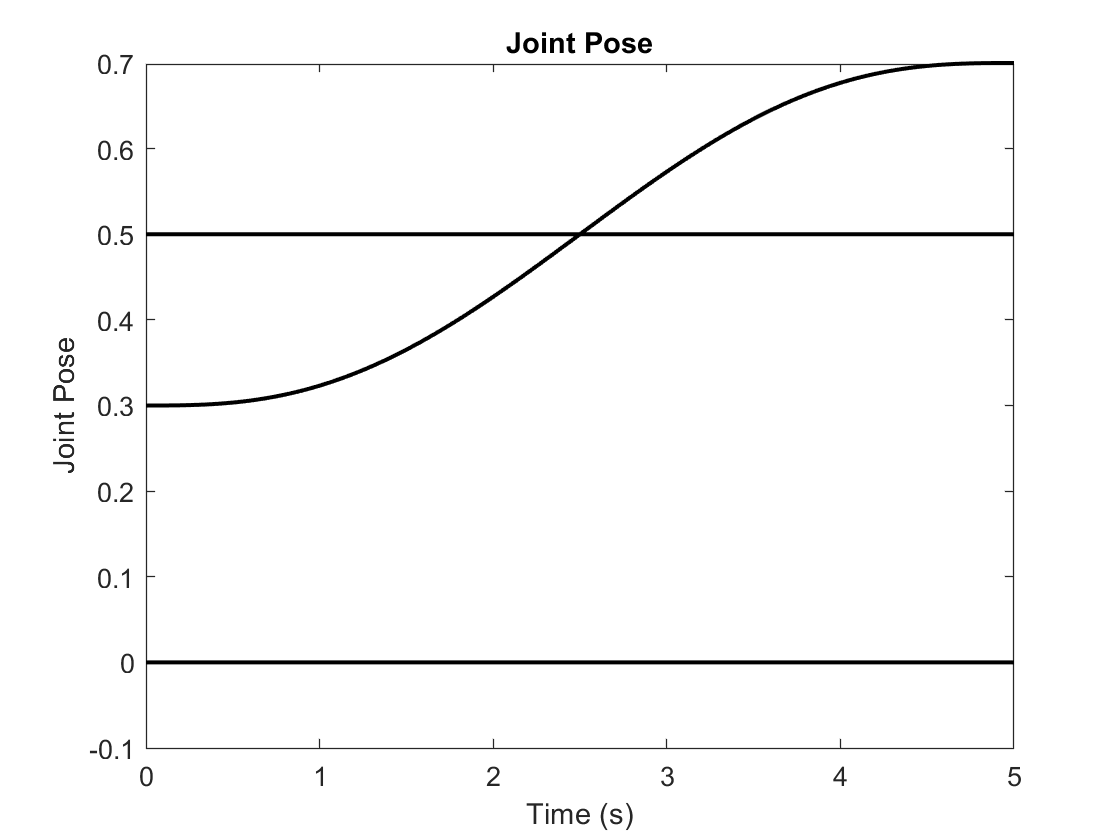

fk_sim_diff.plotJointPose();

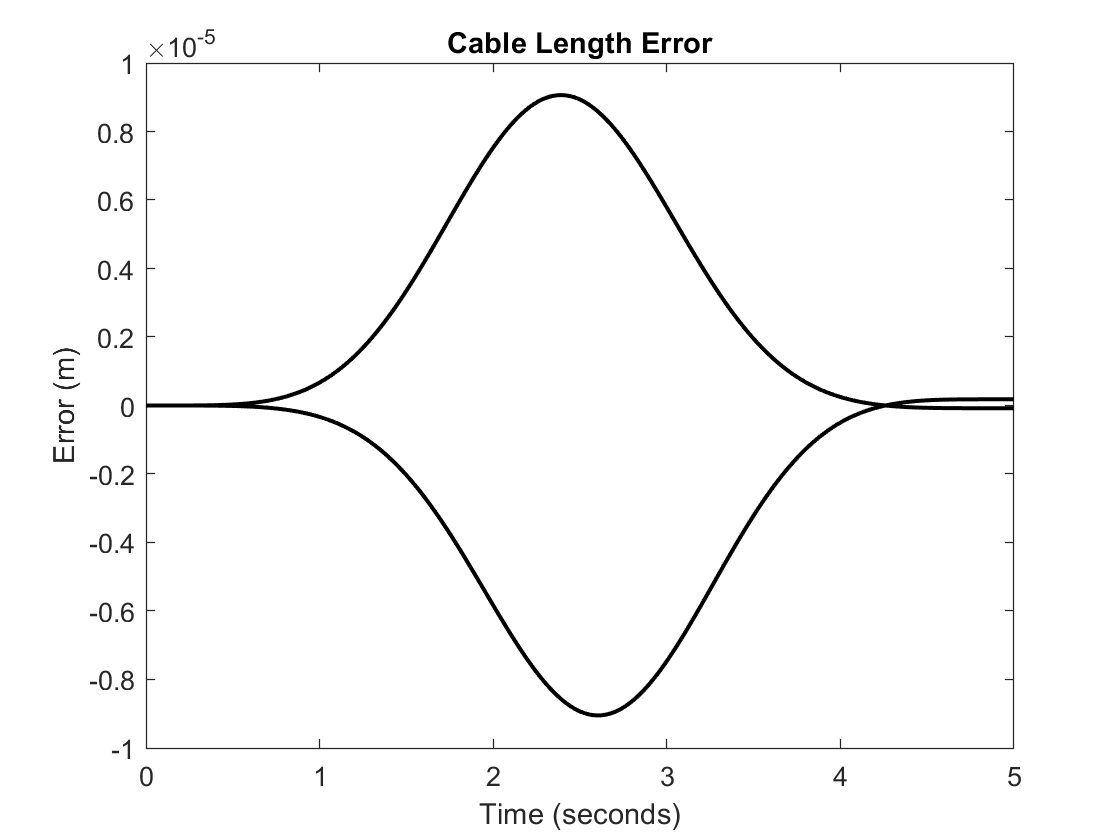

fk_sim_diff.plotCableLengthError();

###     4) Create another simulator with a different solver

    Construct another simulator using the least squares method to compare with

fk_sim_least_squares = ForwardKinematicsSimulator(cdpr_model, fk_least_squares_solver);
fk_sim_least_squares.run(ik_sim.cableLengths, ik_sim.cableLengthsDot, ik_sim.timeVector, init_q, init_q_dot);

[INFO] Begin forward kinematics simulator run...
[INFO] Time : 0.000000
[INFO] Time : 0.010000
[INFO] Time : 0.020000
[INFO] Time : 0.030000
[INFO] Time : 0.040000
[INFO] Time : 0.050000
[INFO] Time : 0.060000
[INFO] Time : 0.070000
[INFO] Time : 0.080000
[INFO] Time : 0.090000
[INFO] Time : 0.100000
[INFO] Time : 0.110000
[INFO] Time : 0.120000
[INFO] Time : 0.130000
[INFO] Time : 0.140000
[INFO] Time : 0.150000
[INFO] Time : 0.160000
[INFO] Time : 0.170000
[INFO] Time : 0.180000
[INFO] Time : 0.190000
[INFO] Time : 0.200000
[INFO] Time : 0.210000
[INFO] Time : 0.220000
[INFO] Time : 0.230000
[INFO] Time : 0.240000
[INFO] Time : 0.250000
[INFO] Time : 0.260000
[INFO] Time : 0.270000
[INFO] Time : 0.280000
[INFO] Time : 0.290000
[INFO] Time : 0.300000
[INFO] Time : 0.310000
[INFO] Time : 0.320000
[INFO] Time : 0.330000
[INFO] Time : 0.340000
[INFO] Time : 0.350000
[INFO] Time : 0.360000
[INFO] Time : 0.370000
[INFO] Time : 0.380000
[INFO] Time : 0.390000
[INFO] Time : 0.400000
[INFO] T

    Again, the performance of the solver can be observed by plotting the resulting joint poses and the cable length error:

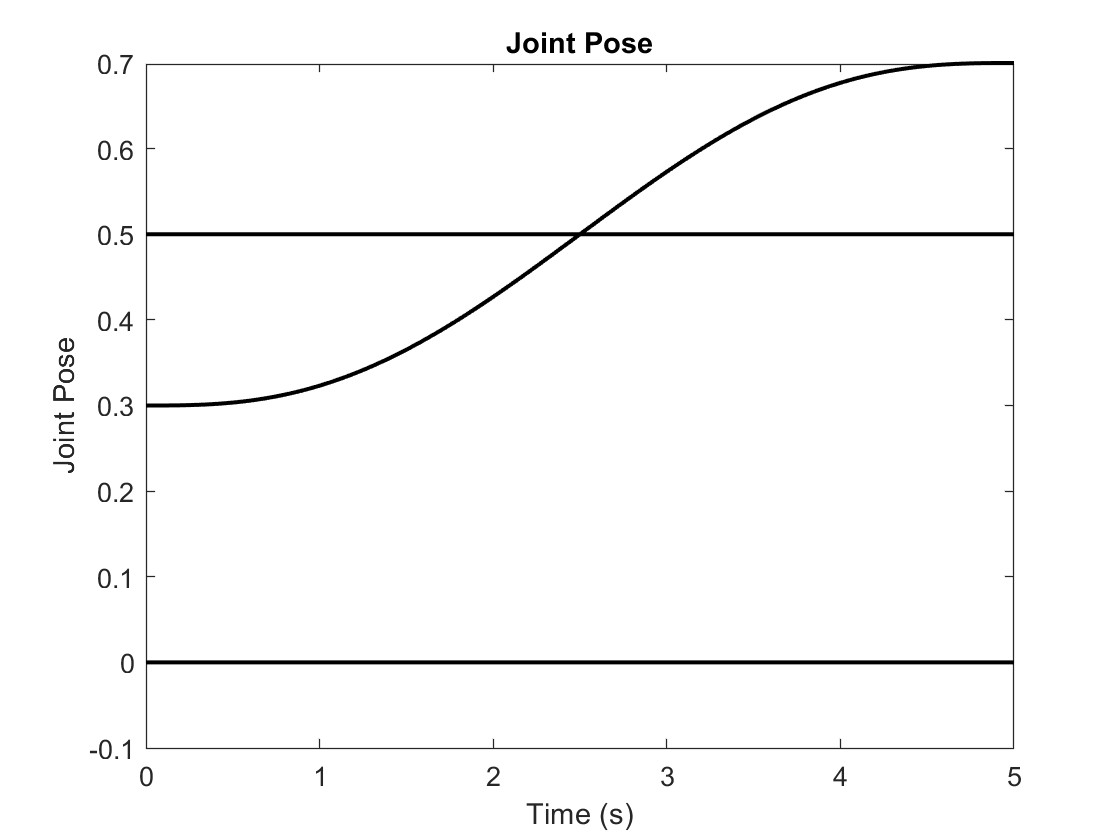

fk_sim_least_squares.plotJointPose();

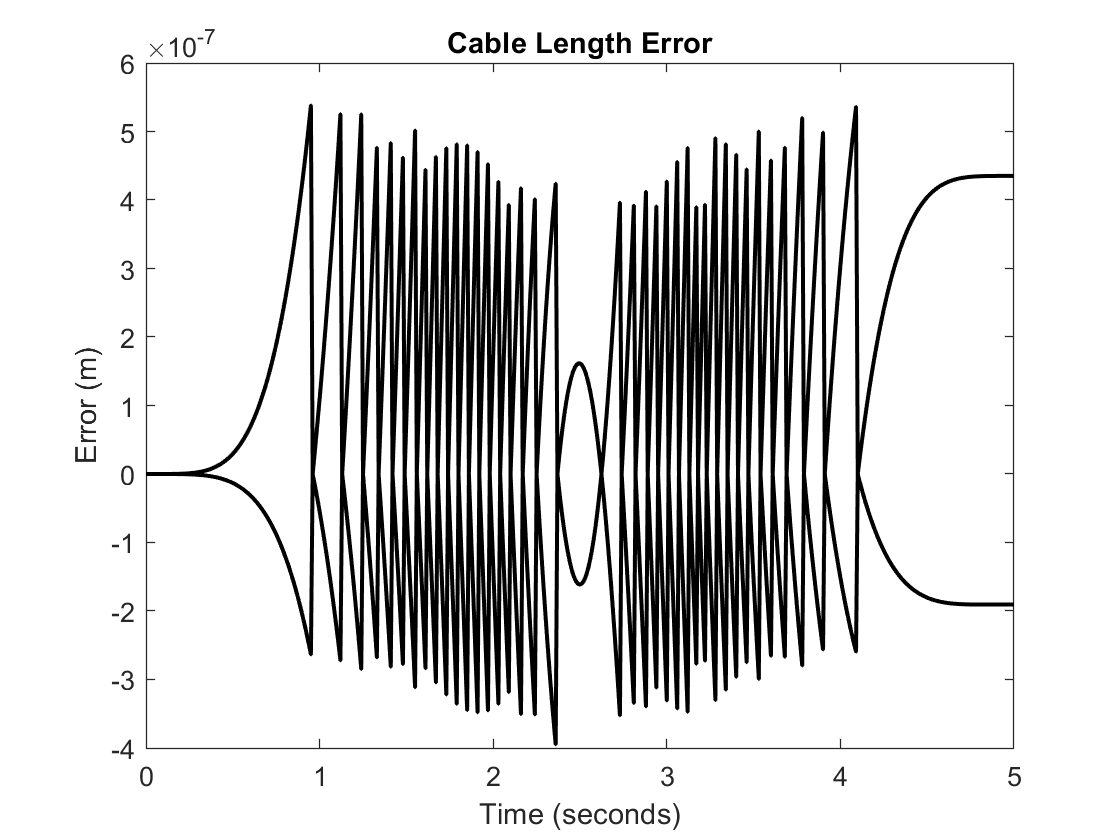

fk_sim_least_squares.plotCableLengthError();

    It can be seen that the least squares method is more accurate (lower error) but is more time consuming. 

% Print information related to the differential method simulation
fprintf('For differential method:\n');

For differential method:


fprintf('Total time: %f seconds\n', fk_sim_diff.compTimeTotal);

Total time: 0.747613 seconds


fprintf('Total length error: %f\n', fk_sim_diff.lengthErrorTotal);

Total length error: 0.002887


% Print information related to the least squares method simulation
fprintf('For least squares method:\n'); 

For least squares method:


fprintf('Total time: %f seconds\n', fk_sim_least_squares.compTimeTotal);

Total time: 5.178222 seconds


fprintf('Total length error: %f\n', fk_sim_least_squares.lengthErrorTotal);

Total length error: 0.000185


## Writing your own time loop

If you want more control over what is happening or customise the inner-workings during the simulation, it is recommended for you to write your own time loop. The following simple example is basically what happens within the Forward`KinematicsSimulator`.

First, create the variables (pre-allocate memory) required to store the solution from the inverse kinematics (cable lengths and cable lengths velocity):

fk_sol_diff = zeros(cdpr_model.numDofs, length(trajectory.timeVector)); % Each column is the solution at each time step
fk_sol_least_squares = zeros(cdpr_model.numDofs, length(trajectory.timeVector)); % Each column is the solution at each time step
comp_time_diff = zeros(length(trajectory.timeVector), 1);
comp_time_least_squares = zeros(length(trajectory.timeVector), 1);

Setup some initial variables, previous length, previous joint pose and previous joint velocity. This is required by the forward kinematics solvers.

len_prev = ik_sim.cableLengths{1};          % Initialise the previous length as the first set of cable lengths
q_prev_diff = init_q;                       % For differential method
q_dot_prev_diff = init_q_dot;               % For differential method
q_prev_leastsquares = init_q;               % For least squares method
q_dot_prev_leastsquares = init_q_dot;       % For least squares method

Next, loop through the trajectory as a function of time:

for t = 1:length(trajectory.timeVector)

The main step within the time loop is to call the solver to resolve the forward kinematics:

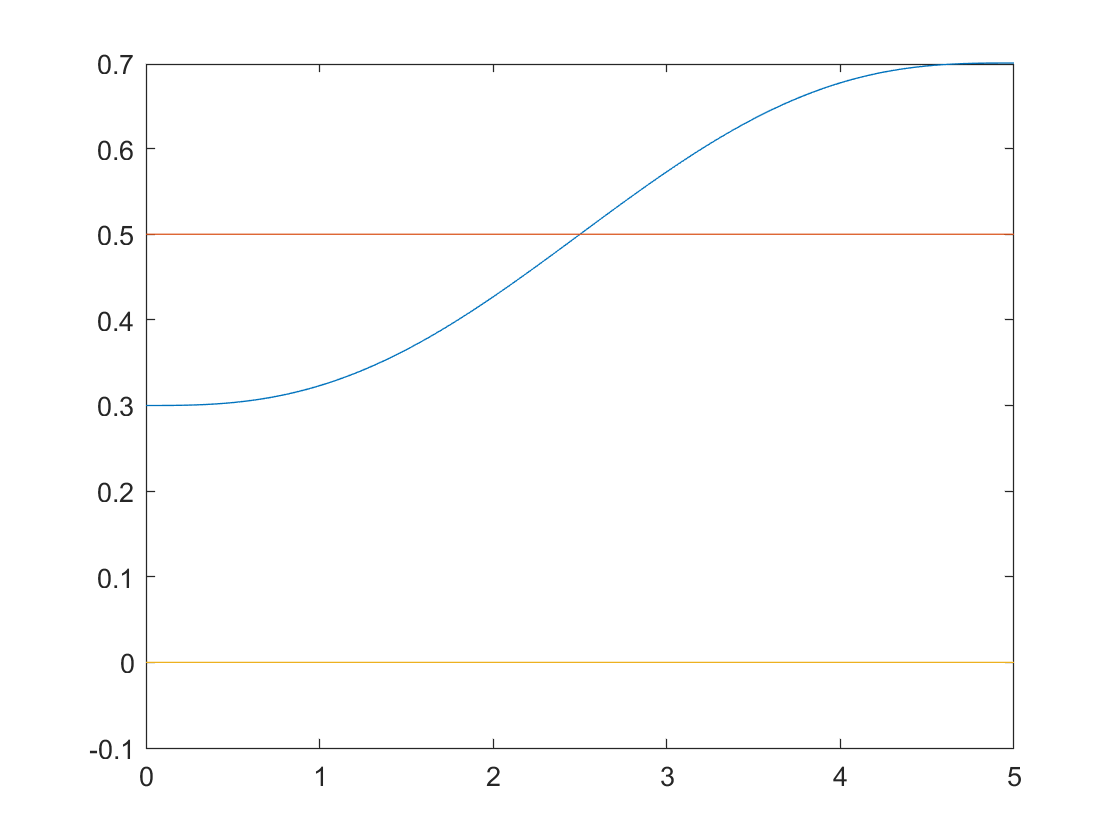

    % Compute for the differential method forward kinematics solver
    [q_sol, q_dot_sol, comp_time_diff(t)] = fk_diff_solver.compute(ik_sim.cableLengths{t}, len_prev, q_prev_diff, q_dot_prev_diff, trajectory.timeStep);
    fk_sol_diff(:, t) = q_sol;

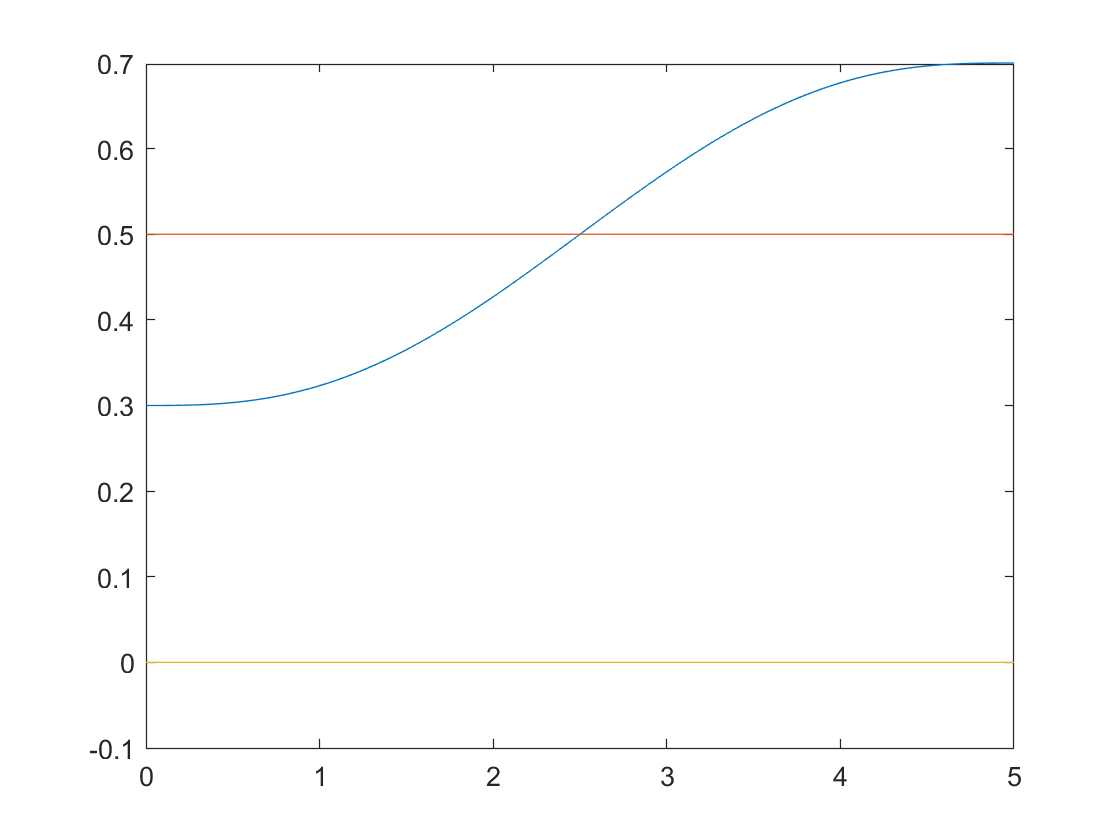

    q_prev_diff = q_sol;
    q_dot_prev_diff = q_dot_sol;

    
    % Compute for the least squares method forward kinematics solver

For differential method:


    [q_sol, q_dot_sol, comp_time_least_squares(t)] = fk_least_squares_solver.compute(ik_sim.cableLengths{t}, len_prev, q_prev_leastsquares, q_dot_prev_leastsquares, trajectory.timeStep);

Total time: 1.091997 seconds


    fk_sol_least_squares(:, t) = q_sol;

For least squares method:


    q_prev_leastsquares = q_sol;

Total time: 6.894478 seconds


    q_dot_prev_leastsquares = q_dot_sol;
    
    % Store cable length for next loop
    len_prev = ik_sim.cableLengths{t};
end

The results can be plotted the way you desire yourself.

figure; 
plot(trajectory.timeVector, fk_sol_diff);
figure; 
plot(trajectory.timeVector, fk_sol_least_squares);

fprintf('For differential method:\n');
fprintf('Total time: %f seconds\n', sum(comp_time_diff));
fprintf('For least squares method:\n'); 
fprintf('Total time: %f seconds\n', sum(comp_time_least_squares));